# LQR using State Estimator

**Sachin C. Patwardhan*, Anjali P. Deshpande and Sharad Bhartiya* **

(*) Dept. of Chemical Engineering,

 Indian Institute of Technology Bombay, Mumbai 400076 India  

## Introduction

 In Modules 3 and 4, we derived fixed gain state feedback laws of the form $u(k)=-Gx(k)$ for unconstrained finite horizon MPC formulation and for the infinite horizon LQOC. While developing these control laws, it was assumed that the state is perfectly measured. In practice, however, *perfect state measurement* is an unrealistic assumption. In the previous module, we developed state estimators that construct an estimate of the state sequence $\left\lbrace \hat{x} \left(k\right):k=1,2,\ldotp \ldotp \ldotp \right\rbrace$ starting from some initial guess $\widehat{x} \left(0\right)$ and the measurement sequence $\left\lbrace y\left(j\right):j=1,2,\ldotp \ldotp \ldotp \ldotp \right\rbrace$. In this lesson we illustrate how the estimated state sequence can be used for implementation of the state feedback control laws. 

**Learning objectives** are: 

- Implement state feedback control law using state estimator (stationary Kalman filter)   

- Carry out the nominal stability analysis of state feedback control law implementation using a state estimator 

- Investigate effect of unmeasured disturbances and model plant mismatch on closed loop behavior under state feedback regulator 

## Nominal Stability Analysis: Separation Principle 

 As stated earlier, the **nominal stability analysis** refers to analyzing the stability of a system **under its nominal (ideal or expected) conditions**, i.e., **without considering uncertainties**, disturbances, or modeling errors. Let us assume that the system dynamics are governed by the ideal discrete time linear model

$x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)$   -------------(1)

 In Modules 3 and 4, we derived fixed gain state feedback laws of the form $u(k)=-Gx(k)$ for unconstrained finite horizon MPC formulation and for the infinite horizon LQOC.  In the case of finite horizon unconstrained MPC controller, the nominal stability had to be established by finding eigenvalues of $\left(\Phi -\Gamma G_{\textrm{MPC}} \right)$. Using Lyapunov's second method, it was shown that the infinite horizon LQOC guarantees closed loop stability and all eigenvalues of $\left(\Phi -\Gamma G_{\infty } \right)$ are strictly inside the unit circle if the system is reachable.

 In the [previous module](matlab:open('../5. State_Estimation_for_MPC/L01_Introduction_to_State_Estimation.mlx')), we developed state estimators of the from 

$\hat{x\;} \left(k+1\right)=\Phi \widehat{x} \left(k\right)+\Gamma u\left(k\right)+Le\left(k\right)$---------(2)

$e\left(k\right)=y\left(k\right)-C\hat{x\;} \left(k\right)$--------(3)

 that construct an estimate of the state $\hat{x} \left(k\right)$ starting from some initial guess $\widehat{x} \left(0\right)$ and the measurement sequence $\left\lbrace y\left(j\right):j=1,2,\ldotp \ldotp \ldotp \ldotp \right\rbrace$. Here, $L$ represents the observer gain matrix. The nominal stability of the estimator error dynamics is guaranteed when $\rho \left(\Phi -LC\right)<1$, where $\rho \left(\ldotp \right)$ denotes the spectral radius of the matrix in brackets. In particular, the steady state Kalman gain matrix, $L=L_{\infty }$, was found by solving the algebraic Riccati equations. Subsequently, using Lyapunov's second method, we also established that eigenvalues of $\left(\Phi -{\mathrm{L}}_{\infty } \;C\right)$ are strictly inside the unit circle if the system is observable. 

Since$x\left(k\right)$ is not known exactly, we implement the state feedback control law using the estimated state, i.e. $u\left(k\right)=-G\hat{x} \left(k\right)$. Thus, the closed loop dynamics are governed by the 

$x\left(k+1\right)=\Phi x\left(k\right)-\Gamma G\;\hat{x} \left(k\right)=\left(\Phi -\Gamma G\right)x\left(k\right)+\Gamma G\;\varepsilon \left(k\right)\;$   -------------(4)

where $\varepsilon \left(k\right)=\left(x\left(k\right)-\hat{x} \left(k\right)\right)$ represents the state estimation error. Subtracting equation (2) from (1), we can show that the estimation error evolves as

 $\varepsilon \left(k+1\right)=\left(\Phi -L\;C\right)\varepsilon \left(k\right)$   ------(5)

Thus, the nominal closed loop system now evolves as the following unforced system 

$\left\lbrack \begin{array}{c}
x\left(k+1\right)\\
\varepsilon \left(k+1\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\left(\Phi -\Gamma G\right) & \Gamma G\\
\left\lbrack 0\right\rbrack  & \left(\Phi -LC\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\left(k\right)\\
\varepsilon \left(k\right)
\end{array}\right\rbrack$    ------(6) 

It is easy to show that the characteristic equation of the closed loop matrix is

 $\det \left(\lambda I-\left(\Phi -\Gamma G\right)\right)\;\det \left(\lambda I-\left(\Phi -L\;C\right)\right)=0$   ------(7)

Note that any state feed back control law is designed such that $\rho \left(\Phi -\Gamma G\right)<1\;\;\textrm{and}\;$any observer designed such that $\rho \left(\Phi -L\;C\right)<1$ . Equation (7) tells us that, if the controller and observer are separately designed to be nominally stable, then their combination gives rise to a nominally stable closed loop system. This is referred to as the ***separation principle***.  In fact, when if we choose $G=G_{\infty }$ and $L=L_{\infty } ,$ the nominal closed loop stability is guaranteed together with performance as eigenvalues of  $\left(\Phi -\Gamma G_{\infty } \right)$ and $\left(\Phi -{\mathrm{L}}_{\infty } \;C\right)$ are strictly inside the unit circle. Thus,  combination of LQR and steady state Kalman filter give rise to a closed loop system with guaranteed nominal stability. 

## Implementation of LQR based on SS KF

We now implement LQR on two different systems. We use steady state Kalman Filter for [state estimation](matlab:open('../5. State_Estimation_for_MPC/L01_Introduction_to_State_Estimation.mlx')).

### Example: Reactor at Unstable Operating Point 

Now, let is look at another example: Continuous Stirred Tank Reactor (CSTR) system operated at the unstable operating point. The system dynamics are governed by the following


$$\left\lbrack \begin{array}{c}
{\delta C}_A \left(k+1\right)\\
\delta T\left(k+1\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0\ldotp 7943 & -0\ldotp 006245\\
11\ldotp 93 & 1\ldotp 256
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\delta C}_A \left(k\right)\\
\delta T\left(k\right)
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0\ldotp 001006 & 0\ldotp 09613\\
-0\ldotp 3673 & -3\ldotp 612
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\delta F}_C \left(k\right)\\
\delta F\left(k\right)
\end{array}\right\rbrack$$


Here, ${\delta C}_A \;\textrm{and}\;\delta T$ represent perturbations in concentration of reactant A and temperature, respectively. Manipulated inputs,  ${\delta F}_C \;\textrm{and}\;\delta F$represent coolant flow to the cooling jacket and flow of the reactant at the reactor inlet, respectively. 

#### Closed Loop Simulation

To observe the results of closed loop simulations for implementation of LQR based on SS KF, press Run This Section Button.

 
clear all 
close all 
clc

% System matrices at the unstable operating condition 
phy=[0.7943 -0.006245 ; 11.93 1.256]; 
gam=[0.001006 0.09613; -0.3673 -3.612]';

C_mat = [ 0 1 ] ; 
samp_T = 0.1 ; 

[n_op, nx ] = size(C_mat)  ;
[n_st, n_ip] = size(gam) ;
gam_d = eye(n_st) ;
[nx, n_d] = size(gam_d) ;

** rho_phy** is the maximum of absolute eigen value of $\Phi$ matrix. Both the eigenvalues lie outside the unit circle as  and the equilibrium point is unstable.

eig_val = eig(phy) ;
rho_phy = max(abs(eig_val)) 

rho_phy = 1.0354

Now we design LQOC. Let us select the following weighting matrices 

 
$$W_x =\left\lbrack \begin{array}{cc}
10 & 0\\
0 & 1
\end{array}\right\rbrack$$
  
$$W_u =\left\lbrack \begin{array}{cc}
5 & 0\\
0 & 50
\end{array}\right\rbrack$$


The LQR gain obtained is

% MPC Tuning Parameters
Wx = diag( [ 10 1 ] ) ;    % State weighting matrix  
Wu =  50 * diag( [0.1  1]) ;     % Input weighting matrix
[G_inf,S_inf, Eig_CL_con] = dlqr(phy, gam, Wx, Wu, zeros(n_st,n_ip)) ;
G_inf

G_inf =     0.3157    0.0279
   -1.9358   -0.1157


This gain is used in computing the control inputs. While applying them to the CSTR system, they are clipped between the upper and lower bounds, if they exceed them.For the CSTR system input flows are bound between 0 and 30 for coolant flow and 0 to 2 for reactant flow. Thus, bounds on perturbation inputs, with reference to $U_s ={\left\lbrack \begin{array}{cc}
3 & 3
\end{array}\right\rbrack }^T$can be defined as follows 

$u_H =\left\lbrack \begin{array}{c}
30\\
2
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
15\\
1
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
15\\
1
\end{array}\right\rbrack \;$  and $u_L =\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
15\\
1
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-15\\
-1
\end{array}\right\rbrack$

We have written a code that  generates matrices needed for specifying these input constraints. 

u_H = [30 2]' - [ 15 1]' ;  % Flow Input bounds 
u_L = [0 0]' - [ 15 1 ]' ;  % Steady state inputs are [15 1] 


** Kalman predictor design **

 Let us now check the [observability](matlab:open('../6. State_Estimation for MPC/L01_IntroductiontoStateEstimation.mlx')) of the system. The observability matrix and rank are displayed below

Q_mat = diag([0.01^2 0.2^2]) ;
R_mat = 0.15^2 ;
n_d = 2 ;
CSTR_sys = ss(phy, [gam gam_d], C_mat, zeros(n_op,n_ip+n_d), samp_T ) ;

obsv_mat = obsv( phy, C_mat ) 

obsv_mat =          0    1.0000
   11.9300    1.2560


 Ro=rank(obsv_mat)

Ro = 2

As the rank of observability matrix is 2, which is equal to the number of states, we can design an observer. Here Kalman predictor is designed using MATLAB command [kalman](https://in.mathworks.com/help/control/ref/ss.kalman.html?websocket=on#mw_3ba98894-fd69-40c7-812d-569904ed6fd4)

 [KEST,L_inf,P_inf] = kalman(CSTR_sys, Q_mat, R_mat, zeros(n_d,n_op),'delayed')  ;
 disp('Kalman gain is')

Kalman gain is


 L_inf

L_inf =     0.0068
    1.2147


We check the stability of the observer by verifying the condition $\rho \left(\Phi -\textrm{LC}\right)<1$

 rho_obs = max(abs(eig(phy - L_inf * C_mat )))

rho_obs = 0.4336

As the eigenvalues lie inside unit circle, the observer is stable.

**Closed loop simulations**

 N = 151 ;      % Simulation run time
 xk = zeros(n_st,N);
yk = zeros(n_op,N) ;
est_err = zeros(n_st,N); 
xkhat = zeros(n_st,N);
xk(:,1) = [ 0.25 -5 ]';
uk = zeros(n_ip,N) ;

**Task: **We can either assume that all the states are measured, in that case estimator_on is set to **No**, meaning that we do not need a state estimator for state estimation. For this case, the controller inputs are obtained as

 
$$u\left(k\right)=-G\;x\left(k\right)$$


If complete state variable is not measured, then we estimate the state by making the variable estimator_on to Yes. In this case the control law is

 
$$u\left(k\right)=-G\hat{x} \left(k\right)$$


Let us select the** estimator_on flag** as **Yes**

estimator_on =1  ; % Set this to zero to use perfect state measurement 

for k = 1:N-1
    kT(k) = (k-1);

    % Control law calculations at sampling instant k 
    if (estimator_on )
        uk_uncon = - G_inf * xkhat(:,k);
        uk_clipped = uk_bound_constraints( uk_uncon, u_L, u_H ) ;
        uk(:,k) = uk_clipped ;
        % Update state estimator from instant k to k+1 using uk
        ek = yk(:,k) - C_mat * xkhat(:,k) ;
        xkhat(:,k+1) = phy * xkhat(:,k) + gam * uk(:,k) + L_inf * ek ;
        est_err(:,k) = xk(:,k) - xkhat(:,k) ;
    else
        uk_uncon = - G_inf * xk(:,k);
        uk_clipped = uk_bound_constraints( uk_uncon, u_L, u_H ) ;
        uk(:,k) = uk_clipped ;
    end

    % Simulate system/plant dynamics from sampling instant k to k+1  
    xk(:,k+1) = phy * xk(:,k) + gam * uk(:,k) ;
    yk(:,k+1) = C_mat * xk(:,k+1) ;
 end
uk(:,N) = uk(:,N-1) ;
kT(N) = N-1 ; 


The following function ensures that the inputs are within the specified bounds. 

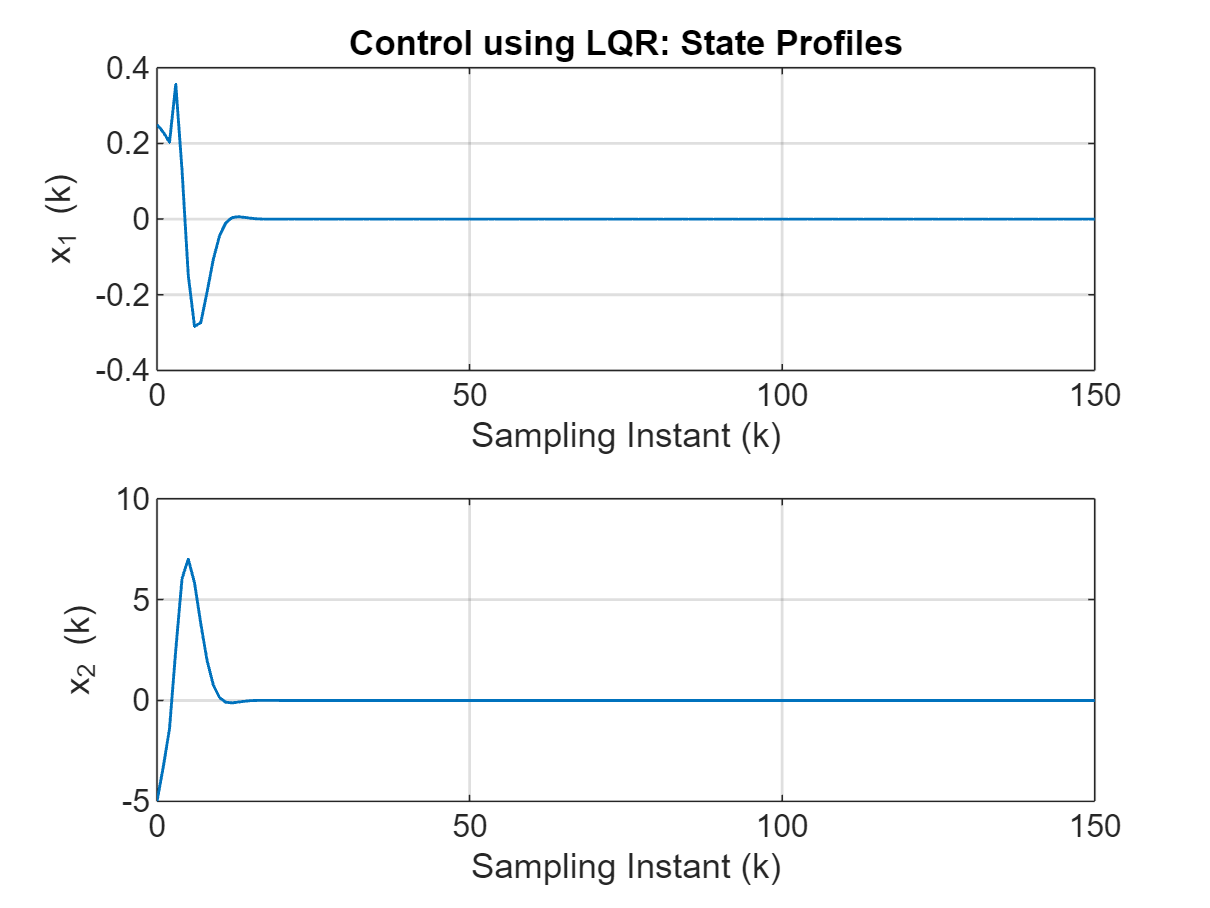

% Function to impose input bounds

function uk_clipped = uk_bound_constraints( u_k, u_L, u_H )

% Ad-hoc implementation of bound constraints

uk_clipped = u_k ; 


if ( u_k(1) <= u_L(1) )   % Impose input constraints on uk(1)
    uk_clipped(1) = u_L(1) ;
elseif ( u_k(1) >= u_H(1) )
    uk_clipped(1) = u_H(1) ;
end
if ( u_k(2) <= u_L(2) ) % Impose output constraints on uk(2)
    uk_clipped(2) = u_L(2) ;
elseif ( u_k(2) >= u_H(2) )
    uk_clipped(2) = u_H(2) ;
end
end

** Display Simulation Results: CSTR Unstable Equilibrium Point **

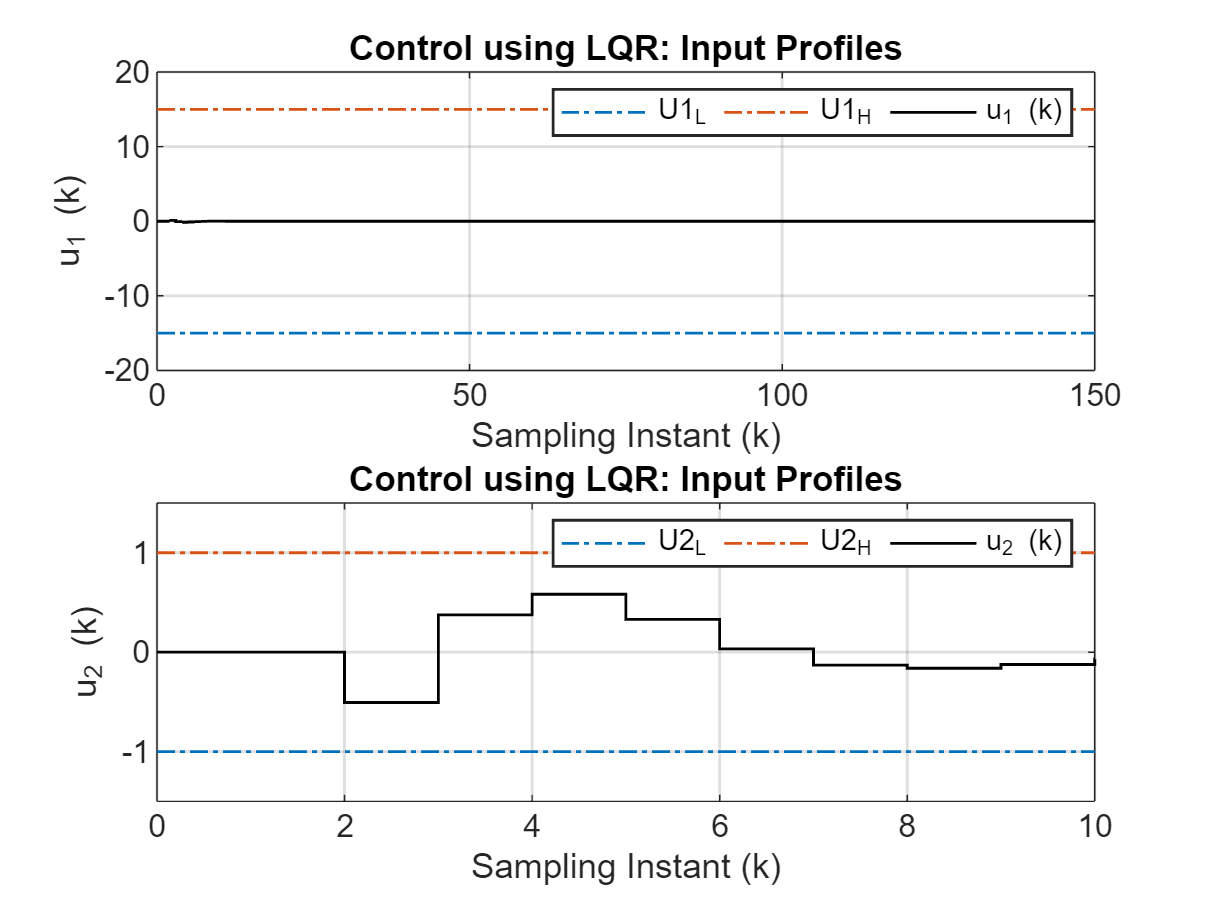

figure(1), subplot(211), plot(kT, xk(1,:)'), grid
xlabel('Sampling Instant (k)'), ylabel('x_1 (k)')
title('Control using LQR: State Profiles')
figure(1), subplot(212), plot(kT, xk(2,:)'), grid

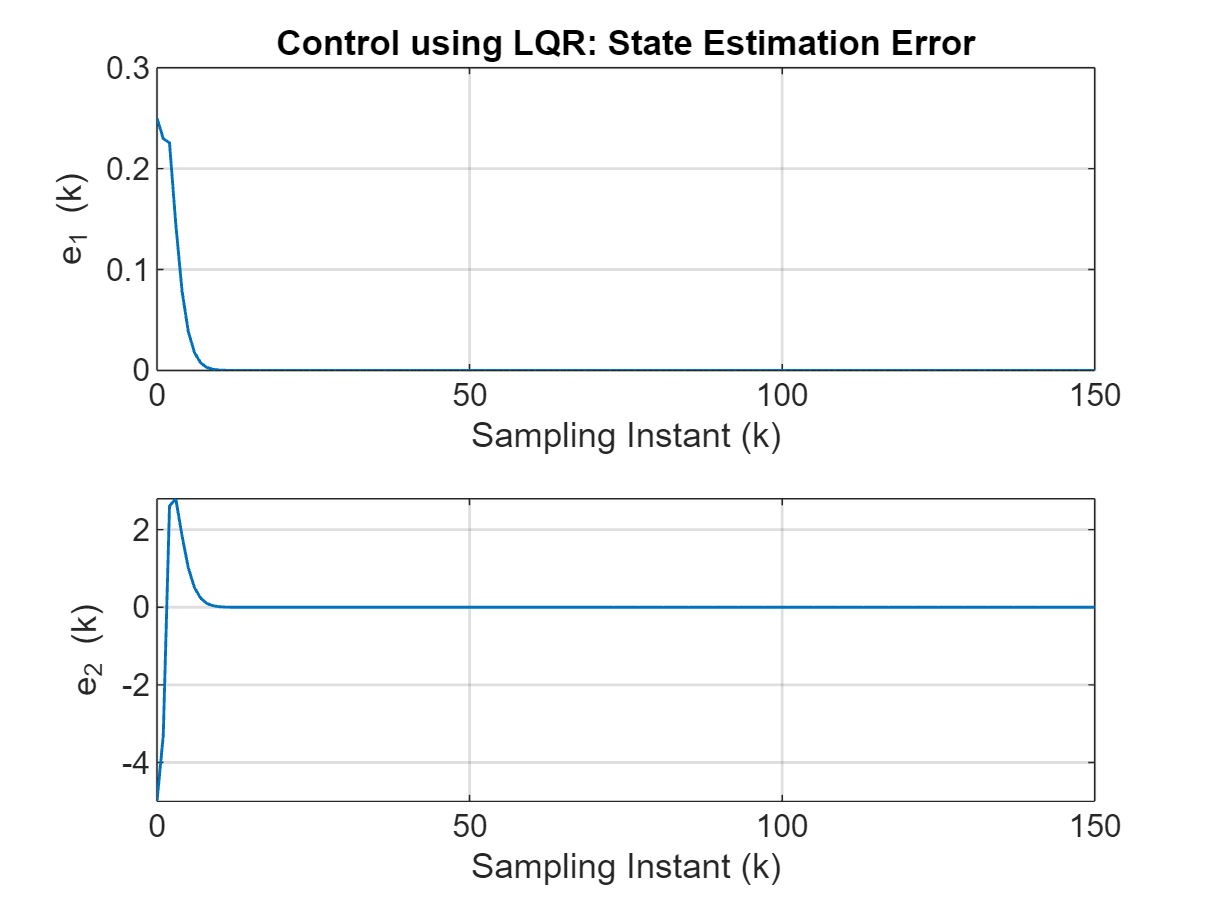

xlabel('Sampling Instant (k)'), ylabel('x_2 (k)')
% Plot Inputs 
U1_mimits = [u_L(1)*ones(N,1) u_H(1)*ones(N,1)]  ;
U2_mimits = [u_L(2)*ones(N,1) u_H(2)*ones(N,1)]  ;
figure(2), subplot(211), stairs(kT, U1_mimits, '-.', 'LineWidth',1), grid

hold on 
stairs(kT, uk(1,:)', 'k', 'LineWidth',1)
hold off
xlabel('Sampling Instant (k)'), ylabel('u_1 (k)'), title('Control using LQR: Input Profiles')
legend( 'U1_L', 'U1_H', 'u_1 (k)', 'Orientation','horizontal')
figure(2), subplot(212), stairs(kT, U2_mimits, '-.', 'LineWidth',1), grid
axis([0 10 -1.5 1.5])
hold on 
stairs(kT, uk(2,:)', 'k','LineWidth',1)
hold off
xlabel('Sampling Instant (k)'), ylabel('u_2 (k)'), title('Control using LQR: Input Profiles')
legend( 'U2_L', 'U2_H', 'u_2 (k)', 'Orientation','horizontal')
figure(3), subplot(211), plot(kT, est_err(1,:)'), grid
xlabel('Sampling Instant (k)'), ylabel('e_1 (k)')
title('Control using LQR: State Estimation Error')
figure(3), subplot(212), plot(kT, est_err(2,:)'), grid
xlabel('Sampling Instant (k)'), ylabel('e_2 (k)')

Thus we can see that the open loop unstable system is controlled using LQR, which is designed using the estimated states by Kalman Filter. Now we can see example of designing state feedback controller based on KF for Q tank process.

### Example: Q-Tank 

Users can press the "*Run This Section"* button to simulate the **LQR with SS KF**  for Q tank process. 

 
clear all
clc
global QTank U_k D_k  % Define global variables for quadruple tank 

Set_Graphics_Parameters ;

N = 150 ; 

**Task 1**: Select the operating point for Q Tank process.  Set it as Non-minimum phase

operating_pt=1;

% Load quadruple tank parameters and steady state 
% The following file loads QTank data structure 
if operating_pt==1
load QTank_MinPhase_Model
else
 load QTank_NonMinPhase_Model 
end

phy= QTank.phy ;  
gam = QTank.gama_u ;
gam_d = QTank.gama_d ; 
C_mat = [1 0 0 0 ; 0 1 0 0]  ; % Levels h(1) and h(2) are measured in quadruple tank 
[n_op, nx ] = size(C_mat)  ;
[n_st, n_ip] = size(gam) ;
[nx, n_d] = size(gam_d) ;


Input weighting matrix


u_H = [5 5]' - QTank.Us ;  % Physical Input bounds low are 0 and 5 Volts 
u_L = [0 0]' - QTank.Us ;  % Steady state inputs are [3 3] 

QT_sys = ss(phy, [gam gam_d], C_mat, zeros(n_op,n_ip+n_d), QTank.samp_T ) ;

Output weighting matrix


Q_mat = 0.0025 ;
R_mat = QTank.R_mat ;

**Task 2:**  LQOC tuning matrices and controller design, LQOC tuning matrices are given as

 $W_y =\left\lbrack \begin{array}{cc}
\alpha_1  & 0\\
0 & \alpha_2 
\end{array}\right\rbrack$,  $W_u =\left\lbrack \begin{array}{cc}
\beta_1  & 0\\
0 & \beta_2 
\end{array}\right\rbrack$, $W_{x}=[C^{T}W_{y}C]   ;   W_{N}=[C^{T}W_{yN}C]$

% LQOC tuning matrices and controller design 
beta(1)=0.095;
beta(2)=0.01;

Controller gain is


disp('Input weighting matrix')

G_inf =     2.6861   -0.1766    0.4359   -0.0203
   -0.0538    3.8390   -0.0083    0.4169


Wu = diag(beta);

Maximum Absolute Closed loop Eigen value


alpha(1)=10;

rho_con = 0.9417

alpha(2)=10;
disp('Output weighting matrix')
Wy = diag(alpha);  % Output weighting matrix
Wx_y = C_mat' * Wy * C_mat ;

Kalman Predictor Gain is


We then compute the controller gain using [dlqr](https://in.mathworks.com/help/control/ref/lti.dlqr.html) command in MATLAB

[G_inf,S_inf, Eig_CL_con] = dlqr(phy, gam, Wy, Wu, zeros(n_st,n_ip)) ;

[G_inf,S_inf, Eig_CL_con] = dlqr(phy, gam, Wx_y, Wu, zeros(n_st,n_ip)) ;

L_inf =     0.0125    0.0168
    0.0173    0.0253
    0.0053    0.0058
    0.0104    0.0121


disp('Controller gain is')

Maximum Absolute Eigen value of phy-LC


G_inf

rho_obs = 0.9464

disp('Maximum Absolute Closed loop Eigen value')
rho_con = max(abs(Eig_CL_con)) 

** Kalman predictor design **

Kalman predictor is designed using MATLAB command [kalman](https://in.mathworks.com/help/control/ref/ss.kalman.html?websocket=on#mw_3ba98894-fd69-40c7-812d-569904ed6fd4)

 [KEST,L_inf,P_inf] = kalman(QT_sys, Q_mat, R_mat, zeros(n_d,n_op),'delayed')  ;
 disp('Kalman Predictor Gain is')
 L_inf
 disp('Maximum Absolute Eigen value of phy-LC')
 rho_obs = max(abs(eig(phy - L_inf * C_mat )))

**Closed Loop simulations**

For this exercise, Q Tank process is simulated using linear discrete time state space model.

 % Closed loop simulations 
xk = zeros(n_st,N);
yk = zeros(n_op,N) ;
est_err = zeros(n_st,N); 
xkhat = zeros(n_st,N);
xk(:,1) =  [3 -3 2 -2]';
uk = zeros(n_ip,N) ;

**Task 3:** We can either assume that all the states are measured, in that case estimator_on is set to No, meaning that we do not need a state estimator for state estimation. 

For this case, the controller inputs are obtained as

 
$$u\left(k\right)=-G\;x\left(k\right)$$


If complete state variable is not measured, then we estimate the state by making the variable estimator_on to Yes. In this case the control law is

 
$$u\left(k\right)=-G\hat{x} \left(k\right)$$


Let us select the estimator_on flag as Yes (Set this to** No** to use perfect state measurement)

estimator_on =1  ; % Set this to No to use perfect state measurement

for k = 1:N-1
    kT(k) = (k-1);

     % Control law calculations at sampling instant k 
     if (estimator_on )
         uk_uncon = - G_inf * xkhat(:,k);
         uk_clipped = uk_bound_constraints( uk_uncon, u_L, u_H ) ;
         uk(:,k) = uk_clipped ;
         % Update state estimator from instant k to k+1 using uk
         ek = yk(:,k) - C_mat * xkhat(:,k) ;
         xkhat(:,k+1) = phy * xkhat(:,k) + gam * uk(:,k) + L_inf * ek ;
         est_err(:,k) = xk(:,k) - xkhat(:,k) ;
     else
         uk_uncon = - G_inf * xk(:,k);
         uk_clipped = uk_bound_constraints( uk_uncon, u_L, u_H ) ;
         uk(:,k) = uk_clipped ;
     end

    % Simulate system/plant dynamics from sampling instant k to k+1  
    xk(:,k+1) = phy * xk(:,k) + gam * uk(:,k) ;
    yk(:,k+1) = C_mat * xk(:,k+1) ;
 end
uk(:,N) = uk(:,N-1) ;
kT(N) = N-1 ; 

**Simulation Results**

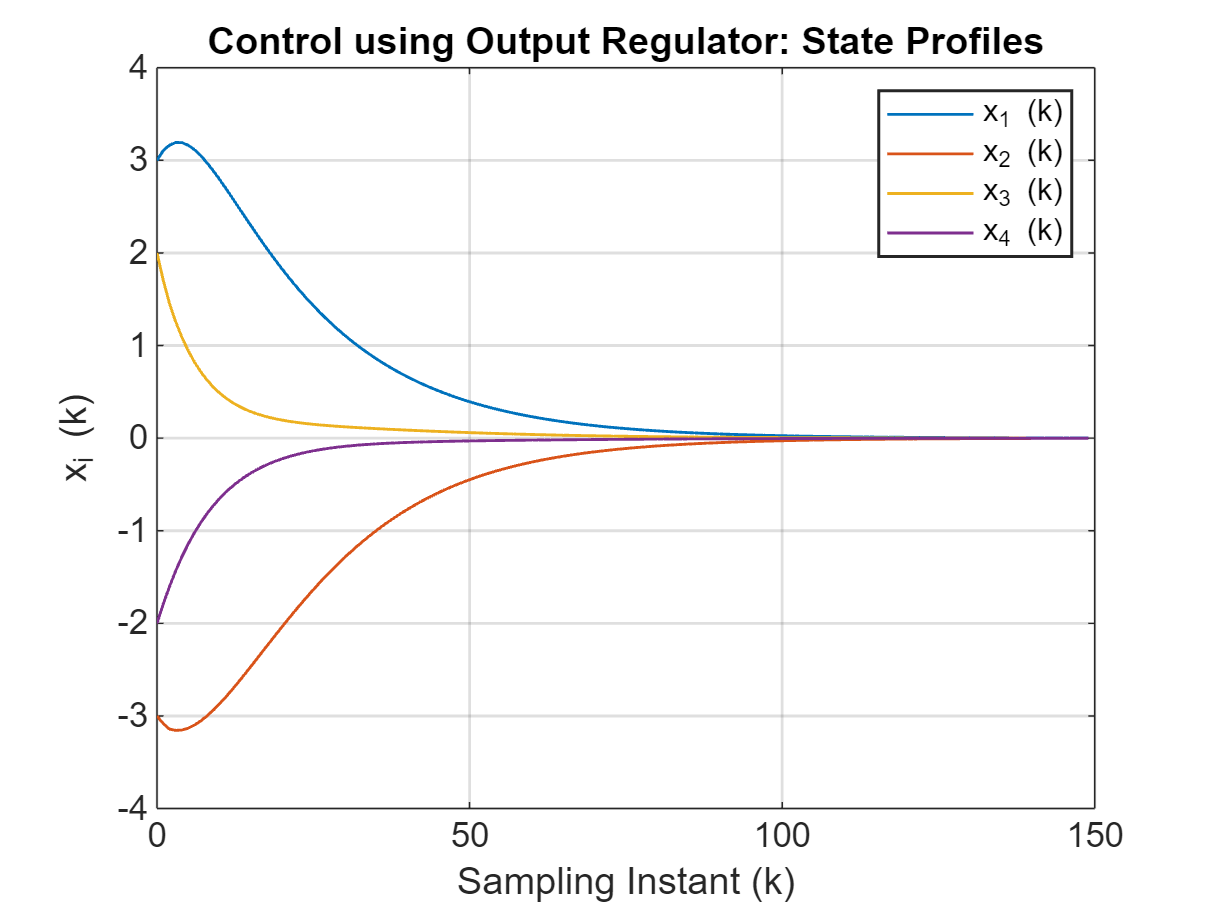

figure(4), plot(kT, xk(1,:), kT, xk(2,:), kT, xk(3,:), kT, xk(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('x_i (k)')
legend('x_1 (k)', 'x_2 (k)', 'x_3 (k)', 'x_4 (k)'), title('Control using Output Regulator: State Profiles')

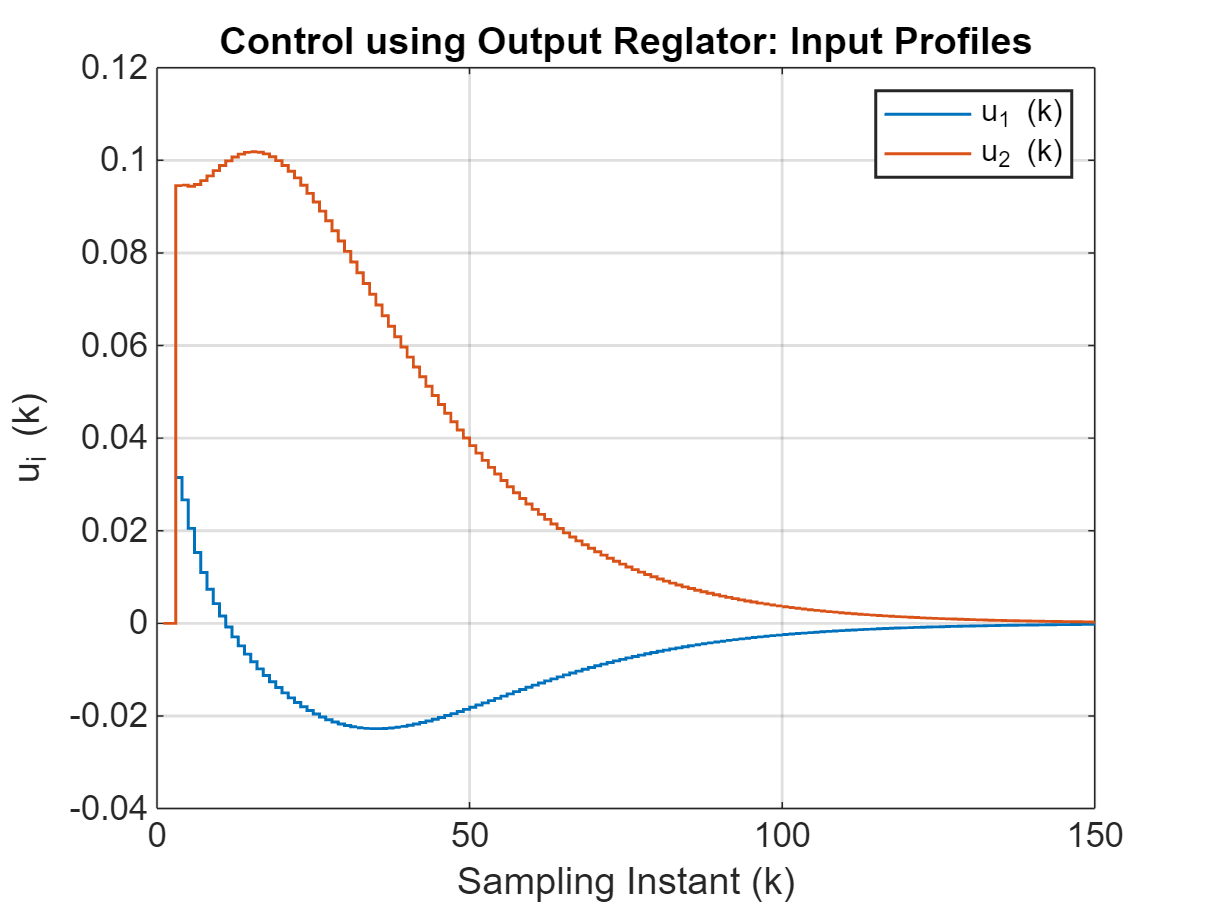

figure(5), stairs(uk', 'LineWidth',1), grid
xlabel('Sampling Instant (k)'), ylabel('u_i (k)'), title('Control using Output Reglator: Input Profiles')
legend('u_1 (k)', 'u_2 (k)')

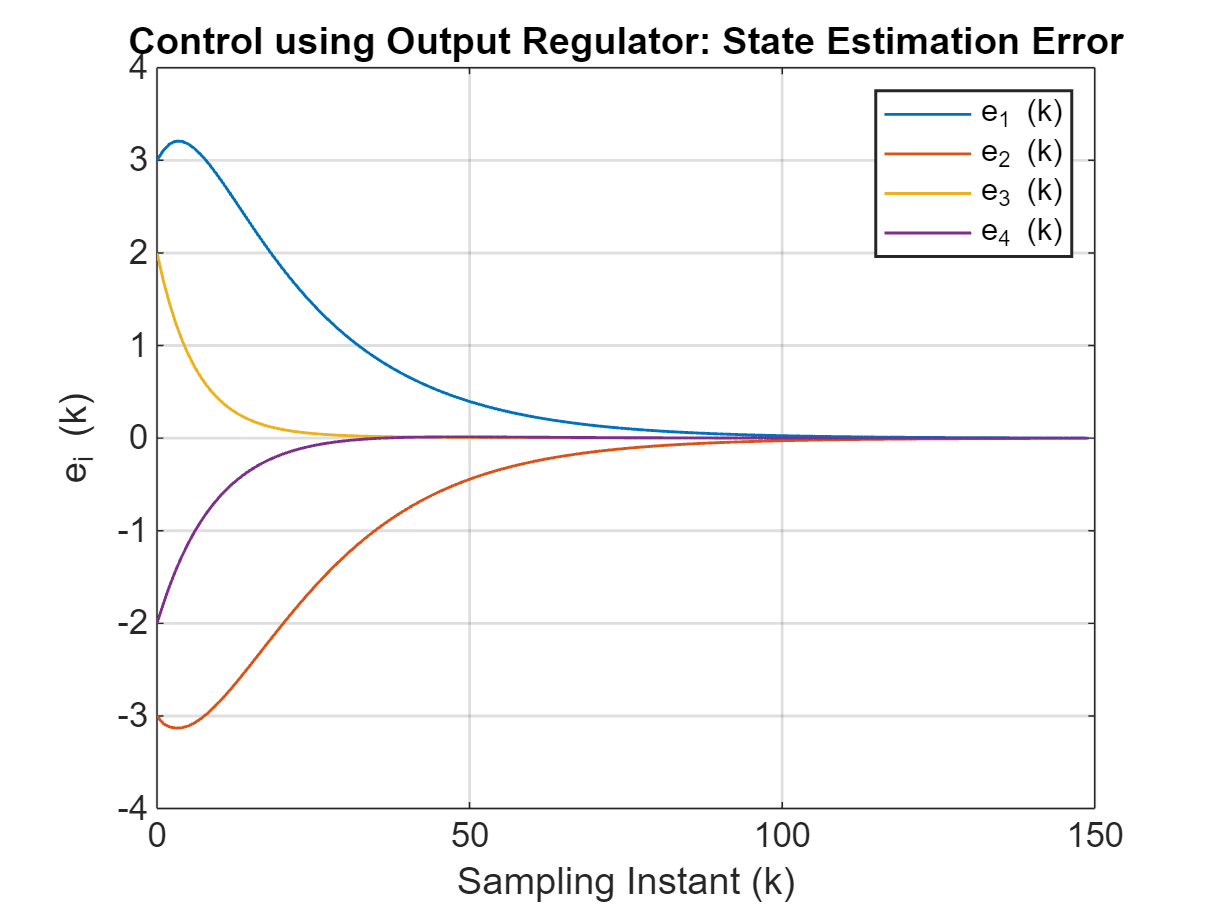

figure(6), plot(kT, est_err(1,:), kT, est_err(2,:), kT, est_err(3,:), kT, est_err(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('e_i (k)')
legend('e_1 (k)', 'e_2 (k)', 'e_3 (k)', 'e_4 (k)'), title('Control using Output Regulator: State Estimation Error')

Observe that the estimation errors have become zero and the states are brought to zero starting from any arbitrary initial states

**Task 4: **Now turn off the estimator_on flag. Observe the controller performance. Is it similar with the controller implemented using Kalman filter estimated states?

**Task 5: **Users can increase or decrease the input and output weighting matrices and observe the effect on closed loop performance of the system.

**Task 6: **Now change the operating point for Q-Tank and repeat the above steps

## Effect of Unmeasured** Disturbances**

If the process dynamics is influenced by nonzero unmeasured disturbances and $x\left(0\right)\not= \bar{0}$, then the system dynamics evolves as follows 

$\begin{array}{l}
x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)+\Gamma_d d\left(k\right)\\
y\left(k\right)=C\;x\left(k\right)
\end{array}$--------------------(8)

The state estimation error dynamics can be obtained by combining observer dynamics with equation (8) as follows 

$\varepsilon \left(k+1\right)=\left(\Phi -\textrm{LC}\right)\varepsilon \left(k\right)+\Gamma_d d\left(k\right)$-------------(9)

Note that in this case, the estimator **error does not decay to zero even when  **$\rho \left(\left(\Phi -L\;C\right)\right)<1$**, due to the presence of the term **$\Gamma_d d\left(k\right)$. Using equation (9) recursively, we can show that 

$\varepsilon \left(k\right)={\left(\Phi -\textrm{LC}\right)}^k \varepsilon \left(0\right)+\sum_{j=0}^{k-1} {\left(\Phi -LC\right)}^{k-j} {\;\;\Gamma }_d d\left(j\right)$  ------(10)

When $\rho \left(\left(\Phi -L\;C\right)\right)<1$, it follows that ${\left(\Phi -\textrm{LC}\right)}^k \to \left\lbrack 0\right\rbrack$ for large *k *and


$$\varepsilon \left(k\right)\to \sum_{j=0}^{k-1} {\left(\Phi -LC\right)}^{k-j} {\;\;\Gamma }_d d\left(j\right)$$


 With the state feedback controller, $u\left(k\right)=-G\;\hat{x} \left(k\right)$, the plant dynamics evolve as

$\begin{array}{l}
x\left(k+1\right)=\Phi x\left(k\right)-\Gamma G\left\lbrack x\left(k\right)-\varepsilon \left(k\right)\right\rbrack +\Gamma_d d\left(k\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\left(\Phi -\Gamma G\right)x\left(k\right)+\Gamma G\varepsilon \left(k\right)+\Gamma_d d\left(k\right)
\end{array}$---------(11)

and  $x\left(k\right)$ **does not go to origin** even when $\rho \left(\Phi -\Gamma G\right)<1$, as the term 2 and 3 on RHS in equation (6) do not go to zero. 

## Effect of Model Plant Mismatch

If the controller is implemented on the real (nonlinear) system then the system dynamics are governed by 

$\begin{array}{l}
X\left(k+1\right)=F\left(X\left(k\right),U\left(k\right),D\left(k\right)\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=F\left(x\left(k\right)+X_s ,u\left(k\right)+U_s ,d\left(k\right)+D_s \right)
\end{array}$  ------(12)

Defining

 $\delta F\left(x\left(k\right),u\left(k\right),d\left(k\right)\right)=F\left(x\left(k\right)+X_s ,u\left(k\right)+U_s ,d\left(k\right)+D_s \right)-X_s \;$  ----(13)

the nonlinear system dynamics can be expressed in terms of deviation variables as follows 

$x\left(k+1\right)=\delta F\left(x\left(k\right),u\left(k\right),d\left(k\right)\right)$ ------(14)

$y\left(k\right)=C\;x\left(k\right)$  ------(15)

Let us assume that the state is estimated using a linear state estimator 

$\hat{x\;} \left(k+1\right)=\Phi \hat{x\;} \left(k\right)+\Gamma u\left(k\right)+L\;e\left(k\right)$  -----(16) 

and the controller $u\left(k\right)=-G\hat{x\;} \left(k\right)$ is implemented on the nonlinear system

$x\left(k+1\right)=\delta F\left(x\left(k\right),-G\hat{x} \left(k\right),d\left(k\right)\right)=\delta F\left(x\left(k\right),-G\left(x\left(k\right)-\varepsilon \left(k\right)\right),d\left(k\right)\right)$  ------(17)

For the purpose of analysis, adding and subtracting $\left(\Phi -\Gamma G\right)x\left(k\right)$ on R.H.S. of equation (17) and rearranging, let us express the nonlinear system dynamics as follows 

$x\left(k+1\right)=\left(\Phi -\Gamma G\right)x\left(k\right)+g\left(x\left(k\right),\varepsilon \left(k\right),d\left(k\right)\right)$  -------(18)

where 

$g\left(x\left(k\right),\varepsilon \left(k\right),d\left(k\right)\right)=\delta F\left(x\left(k\right),-G\left(x\left(k\right)-\varepsilon \left(k\right)\right),d\left(k\right)\right)-\left(\Phi -\Gamma G\right)x\left(k\right)$  ------(19)

represents the plant model mismatch (MPM) signal. Since 

$e\left(k\right)=y\left(k\right)-C\hat{x} \left(k\right)=C\left(x\left(k\right)-\hat{x} \left(k\right)\right)=C\varepsilon \left(k\right)$  ------(20)

the observer evolves as

$\hat{x\;} \left(k+1\right)=\left(\Phi -\Gamma G\right)\hat{x} \left(k\right)+L\;C\varepsilon \left(k\right)$  -------(21)

Subtracting (12) from (11), the estimation error evolves as 

$\varepsilon \left(\left.k+1\right)=\left(\left(\Phi -\Gamma G\right)-L\;C\right)\varepsilon \left(k\right)+g\left(x\left(k\right),\varepsilon \left(k\right),d\left(k\right)\right)\right)$ --------(22)

Thus, the estimator error does not decay to zero even when $\rho \left(\Phi -L\;C\right)<1$ and $x\left(k\right)$ does not tend to the origin even when $\rho \left(\Phi -\Gamma G\right)<1$, because of the MPM term given by equation (19).

## **Q-Tank Regulation under MPM and Disturbance**

global QTank U_k D_k
N = 551 ; 
clear kT
xk = zeros(n_st,N);
yk = zeros(n_op,N) ;
est_err = zeros(n_st,N); 
xkhat = zeros(n_st,N);
xk(:,1) = [1 -1 1 -1]';
uk = zeros(n_ip,N) ;
dk = zeros(1,N) ;

**Task 4:** Select Plant_Sim as Nonlinear for simulating Q Tank process using a nonlinear ODE model. This results in plant model mismatch

Plant_Sim =0  ; 
%% 0 Nonlinear plant simulation 1: Linear plant simulation 

** Disturbance input **

Further we add disturbance input to the process. A time varying disturbance input signal is generated using **idinput** command in MATLAB

dk_prbs = 0.2 * idinput(401, 'rgs', [0.0 0.025] ) ;  
dk(151:end) = 0.4 + dk_prbs ; 
for k = 1:N-1
    kT(k) = (k-1);

    % Control law calculations at sampling instant k 
    uk_uncon = - G_inf * xkhat(:,k);
    uk_clipped = uk_bound_constraints( uk_uncon, u_L, u_H ) ;
    uk(:,k) = uk_clipped ; 

    % Update state estimator from instant k to k+1 using uk 
    ek = yk(:,k) - C_mat * xkhat(:,k) ;
    xkhat(:,k+1) = phy * xkhat(:,k) + gam * uk(:,k) + L_inf * ek ;
    est_err(:,k) = xk(:,k) - xkhat(:,k) ;

     % Quadruple tank Plant Simulation from k to k+1

    if (Plant_Sim )
        xk(:,k+1) = phy * xk(:,k) + gam *uk(:,k) + gam_d * dk(k)  ;
    else
        U_k = QTank.Us + uk(:,k);  D_k =  QTank.Ds + dk(k)  ;
        [T,Xt] = ode45( 'QTank_Dynamics' , [ 0 QTank.samp_T ], QTank.Xs+xk(:,k)) ;   % Nonlinear plant simulation
        xk(:,k+1) = Xt( end,: )' - QTank.Xs ;
    end
    yk(:,k+1) = C_mat * xk(:,k+1) ;

 end
uk(:,N) = uk(:,N-1) ;
est_err(:,N) =  est_err(:,N-1) ;
kT(N) = N-1 ;


**Simulation Results:Effect of Plant Model Mismatch**

Xk = QTank.Xs + xk ;   Uk = QTank.Us + uk ; Dk = QTank.Ds + dk ;
Yk = yk + C_mat * QTank.Xs ;  
u_limit = [u_L(1)*ones(N,1) u_H(1)*ones(N,1)]  ;

**Controlled output profiles **

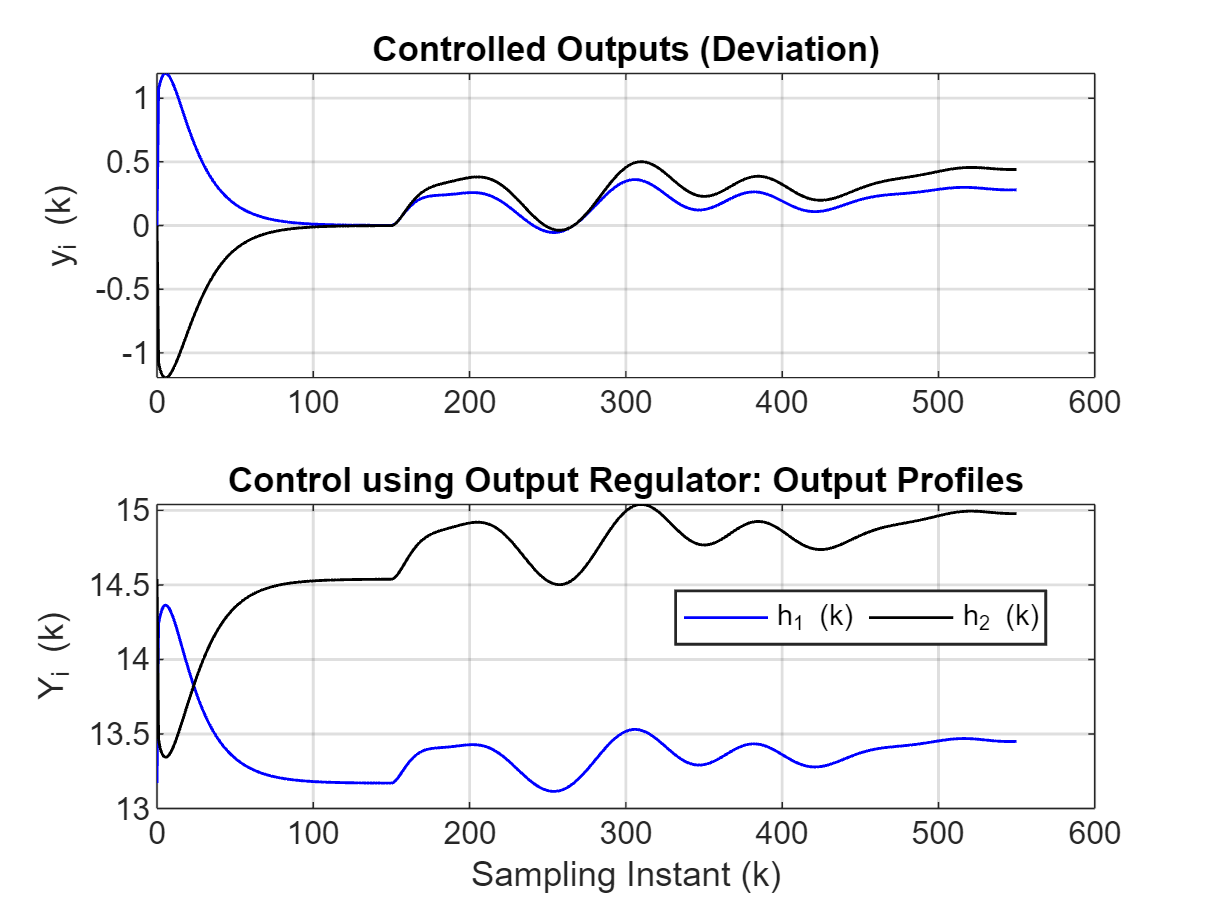

figure, subplot(211), 
plot(kT, yk(1,:), 'b', kT, yk(2,:), 'k'), grid
title('Controlled Outputs (Deviation)'), ylabel('y_i (k)')
subplot(212), plot(kT, Yk(1,:), 'b',  kT, Yk(2,:), 'k'), grid
xlabel('Sampling Instant (k)'), ylabel('Y_i (k)')
legend('h_1 (k)',  'h_2 (k)',  'Orientation','horizontal','Location','Best')
title('Control using Output Regulator: Output Profiles')

**Manipulated input profiles**

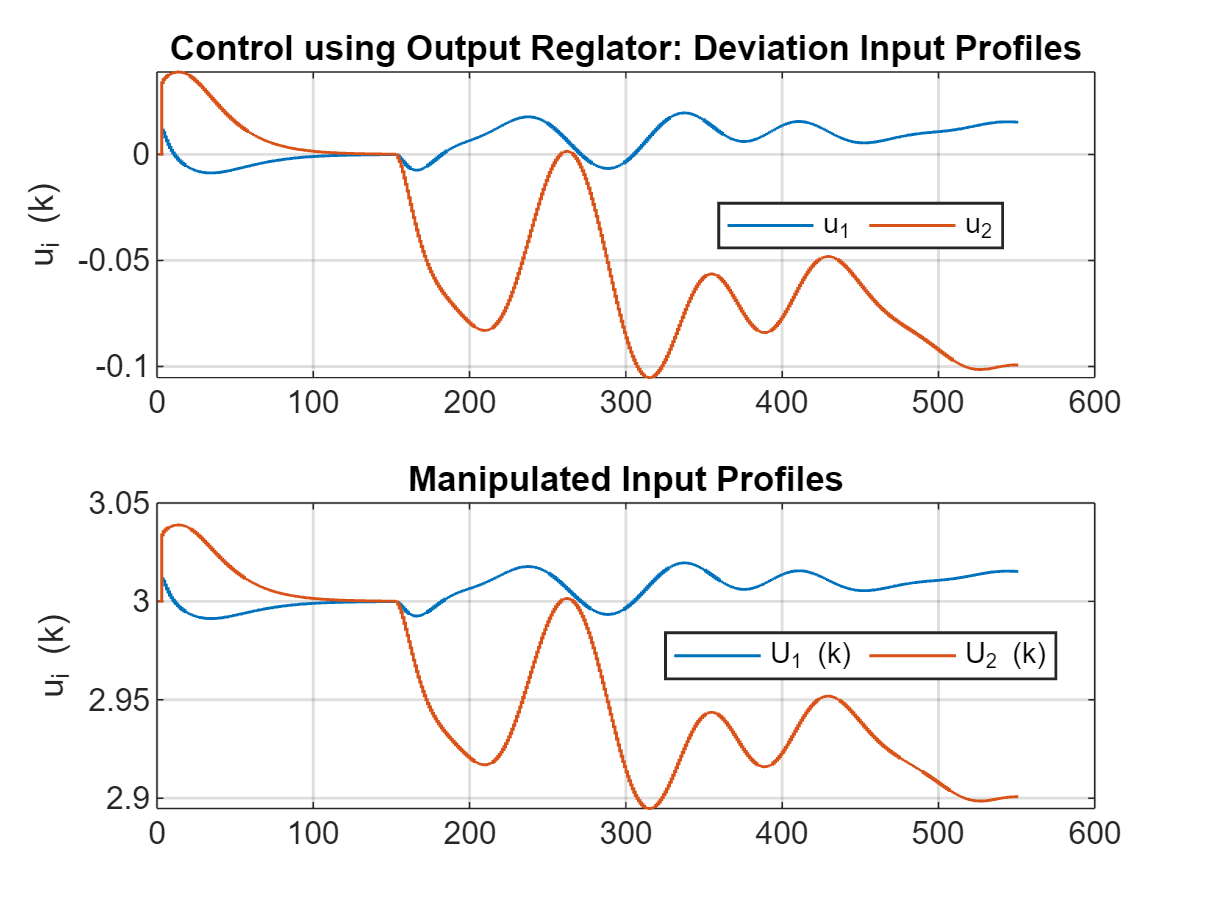

figure, subplot(211), 
stairs(uk', 'LineWidth',1), grid
ylabel('u_i (k)'), title('Control using Output Reglator: Deviation Input Profiles')
legend(  'u_1', 'u_2', 'Orientation','horizontal','Location','Best')
subplot(212), stairs( Uk', 'LineWidth',1),  grid
ylabel('u_i (k)')
title('Manipulated Input Profiles')
legend( 'U_1 (k)', 'U_2 (k)','Orientation','horizontal','Location','Best')

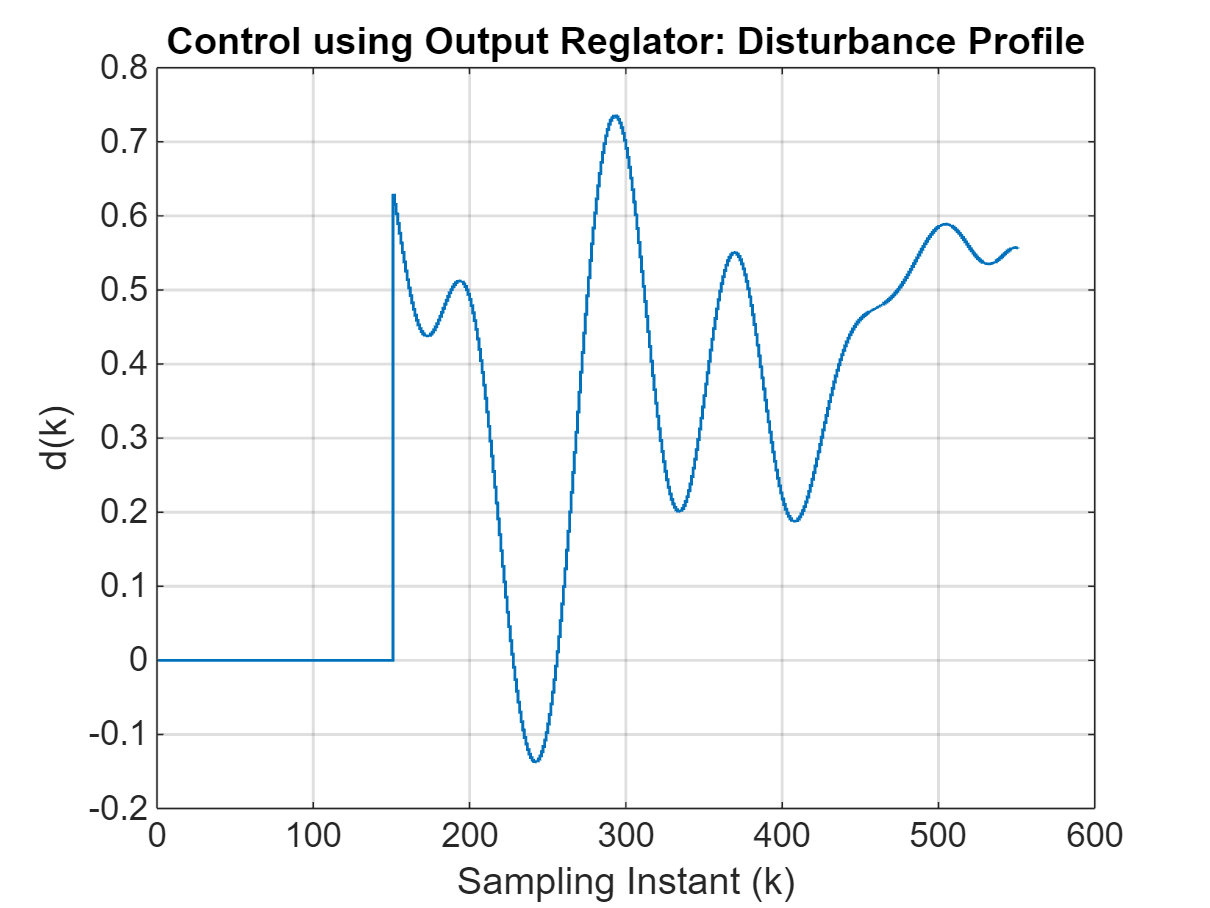

figure, stairs(dk, 'LineWidth',1), grid
xlabel('Sampling Instant (k)'), ylabel('d(k)'), title('Control using Output Reglator: Disturbance Profile')

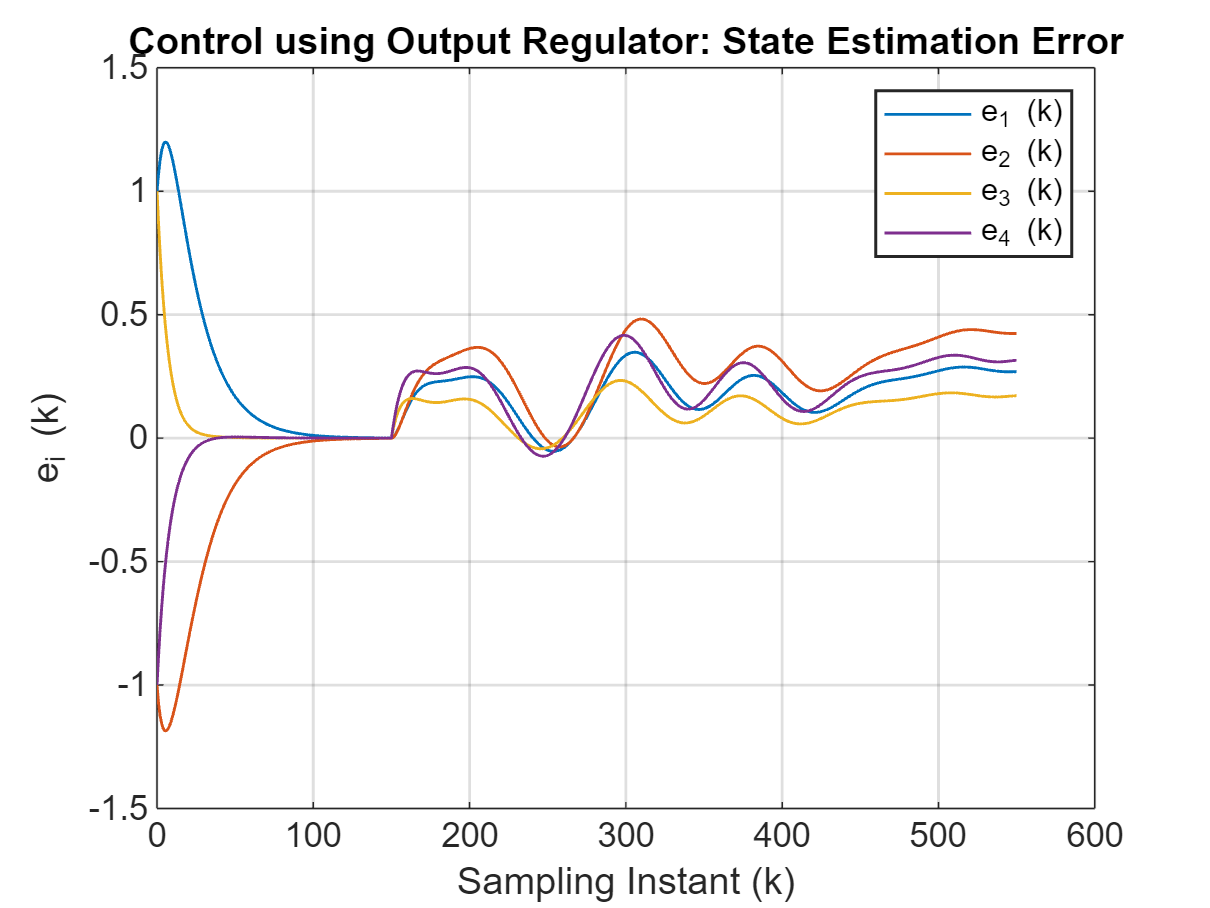

figure, plot(kT, est_err(1,:), kT, est_err(2,:), kT, est_err(3,:), kT, est_err(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('e_i (k)')
legend('e_1 (k)', 'e_2 (k)', 'e_3 (k)', 'e_4 (k)'), title('Control using Output Regulator: State Estimation Error')

Thus, the state feedback regulator generates an offset if the unmeasured disturbances influencing state dynamics are non-stationary, i.e. they have slowly drifting behavior, and the feedback introduced through state estimation is not sufficient to eliminate the offset. 

## Conclusions 

In practice, state feedback controllers have to be implemented using states estimated from state estimators, which combine measurements with model predictions. This lesson has demonstrated how LQOC can be implemented using a stationary Kalman predictor. Moreover, the use of a state estimator has facilitated implementation of a LQR on a CSTR system at an unstable operating point. In the later section of the lesson, we found that the measurement feedback introduced through state estimation is not sufficient to deal with drifting unmeasured disturbances and MPM arising from nonlinear plant dynamics. Modifications necessary to achieve offset free control under these conditions will be discussed in the next lesson. 